**Lab 2: Probability, Distributions, and Statistical Questions**

**Problem 1**

I will assume that in 1 day, the average cosmic-ray background is 3, and the number of gamma-rays emitted by my sample is 7.1. 

*A) Show how the probability distribution changes as you integrate for more days.*

First, I want to setup the probability distribution for 1 day.

pDist1day = makedist("Poisson","lambda",3);

Next, I want to account for multiple days, so I will multiply the values of the distribution by N, where N is the number of days.

N = 5; %choice to be specified later on
x = -20:20;%vector of x inputs
pdfPDist1day = pdf(pDist1day,x);
pdfPDistNdays = pdfPDist1day*N;

pDistNdays is now the probability density function for N days.

We can now compare the pdfs for 1 day and N days, varying N, and see how they change.

subplot(3,1,1);
plot(x,pdfPDist1day);
title('pdf for 1 day');
subplot(3,1,2);
plot(x,pdfPDistNdays);
name = strcat('pdf for ',num2str(N),' days');
title(name);

Change N to be 12 days.

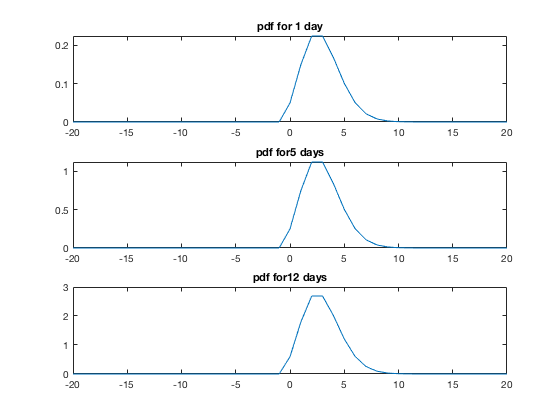

N = 12;
pdfPDistNdays = pdfPDist1day*N;
subplot(3,1,3);
plot(x,pdfPDistNdays);
name = strcat('pdf for ',num2str(N),' days');
title(name);

Let's look at them in a log y-scale as well.

We can see that changing the number of days scales the probability distribution along the vertical axis. Therefore, it is clear that integrating the new probability distributions (which are no longer normalized) will yield vastly different results.